# `Лабораторная работа № 2 `

## `Вариант № 12`

### `Ход работы`

#### `Инициализация коеф варианта и построение графика.`

`W- весовой коэффициент`

W = -8;

`P– коэффициент смещения.`

p = 2;
x = -10:1:10;

`Формула прямой y = W * x + p`

y = W .* x + p;

`График функции прямой `

plot(x,y),grid on ,box off , xlabel("X"),ylabel("Y"),title("График прямой y = -8x + 2");

#### `Формирование 2х множеств точек: 10 черных и 10 белых. Формирование обучающей выборки на основе координат точек.`

`Координаты 10 черных точек `

points_X_Black = [-8 -6 -5 -3 -2 -1  2 4 6 8]

points_X_Black =     -8    -6    -5    -3    -2    -1     2     4     6     8


points_Y_Black = [-60 -40 -25 -44 -25 -15 -60 -65 -75 -78]

points_Y_Black =    -60   -40   -25   -44   -25   -15   -60   -65   -75   -78


`Координаты 10 белых точек`

% Изменить координаты точек согласно варианту!
points_X_White = [-9 -8 -7 -6 -5 -3 -2 -1 4 8]

points_X_White =     -9    -8    -7    -6    -5    -3    -2    -1     4     8


points_Y_White = [95 87 90 75 66 47 35 20 0 -40]

points_Y_White =     95    87    90    75    66    47    35    20     0   -40


`Матрица координат `

P = [points_X_Black points_X_White;points_Y_Black points_Y_White]

P =     -8    -6    -5    -3    -2    -1     2     4     6     8    -9    -8    -7    -6    -5    -3    -2    -1     4     8
   -60   -40   -25   -44   -25   -15   -60   -65   -75   -78    95    87    90    75    66    47    35    20     0   -40


`T – одномерный массив, определяет к какому множеству относятся точки. `

`Принято для точек, лежащих выше прямой («белых») указывать 1, а для точек ниже прямой («черных») – указывать 0. Количество элементов массива T равно количеству столбцов массива P и «цветовая принадлежность» указывается в том же порядке, что и координаты точек в массиве P`

T = [0 0 0 0 0 0 0 0 0 0 ...
    1 1 1 1 1 1 1 1 1 1]

T =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


`Построение графика функции и добавление на него множест точек`

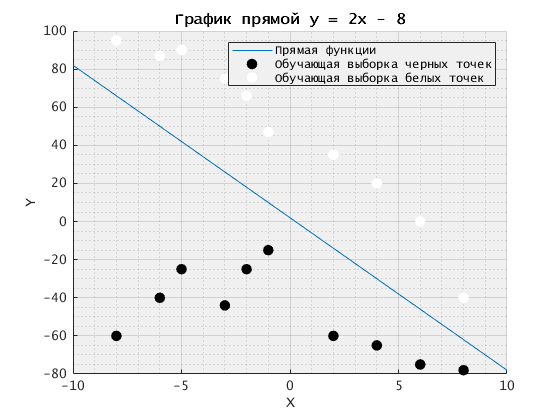

% Create figure
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Create plot
plot(x,y,'DisplayName','Прямая функции');

% Create scatter
scatter(points_X_Black,points_Y_Black,...
    'DisplayName','Обучающая выборка черных точек',...
    'MarkerEdgeColor',[0 0 0],...
    'LineWidth',2,...
    'MarkerFaceColor',[0 0 0]);

% Create scatter
scatter(points_X_Black,points_Y_White,...
    'DisplayName','Обучающая выборка белых точек',...
    'MarkerEdgeColor',[1 1 1],...
    'LineWidth',2,...
    'MarkerFaceColor',[1 1 1]);

% Create ylabel
ylabel('Y','FontName','Lucida Console');

% Create xlabel
xlabel('X','FontName','Lucida Console');

% Create title
title('График прямой y = 2x - 8');

grid(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'Color',[0.941176470588235 0.941176470588235 0.941176470588235],...
    'FontName','Lucida Console','FontSize',10,'XMinorGrid','on','YMinorGrid',...
    'on');
% Create legend
legend(axes1,'show')

figure(figure1);

#### `Вывести документацию к команде newp и ознакомится с примером`

help newp

 newp Create a perceptron.
 
  Obsoleted in R2010b NNET 7.0.  Last used in R2010a NNET 6.0.4.
 
   Syntax
 
     net = newp(p,t,tf,lf)
 
   Description
 
     Perceptrons are used to solve simple (i.e. linearly
     separable) classification problems.
 
     NET = newp(P,T,TF,LF) takes these inputs,
       P  - RxQ matrix of Q1 representative input vectors.
       T  - SxQ matrix of Q2 representative target vectors.
       TF - Transfer function, default = 'hardlim'.
       LF - Learning function, default = 'learnp'.
     Returns a new perceptron.
 
     The transfer function TF can be HARDLIM or HARDLIMS.
     The learning function LF can be LEARNP or LEARNPN.
 
   Examples
 
     This code creates a perceptron layer with one 2-element
     input (ranges [0 1] and [-2 2]) and one neuron. (Supplying
     only two arguments to newp results in the default perceptron
     learning function LEARNP being used.)
 
       net = newp([0 1; -2 

#### `Создание однослойного персептрона с 2мя входами и 1м выходом. Обучение его на сформированных векторах с 10 шагами обучения.`

p_12 = newp(P,T);
p_12.adaptParam.passes = 10;
p_12 = train(p_12,P,T);

#### `Проверка правильности обучения на обучающей выборке.`

sim(p_12,P);

#### `Формирование новой разделяющей прямой после обучения ней`

plotpv(P,T); hold on
plotpc(p_12.IW{1,1},p_12.b{1}); hold on
y = W*P(1,:) + p

y =     66    50    42    26    18    10   -14   -30   -46   -62    74    66    58    50    42    26    18    10   -30   -62


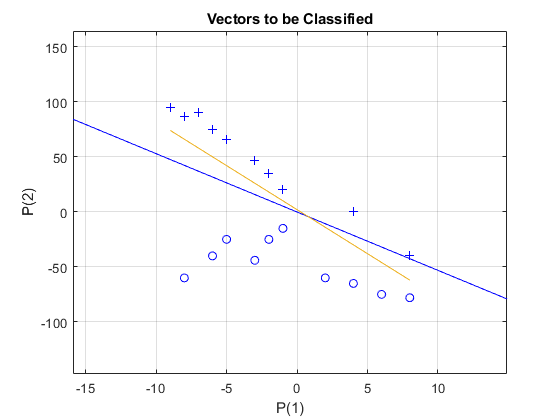

plot(P(1,:),y),grid;